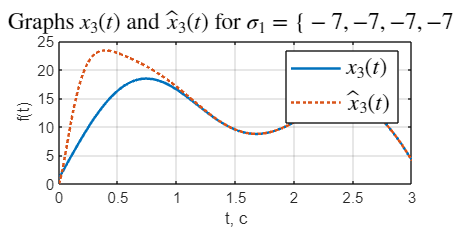

open_system('task_2_sim');
set_param('task_2_sim/x_', 'VariableName', 'x_')
set_param('task_2_sim/x', 'VariableName', 'x')
set_param('task_2_sim/e', 'VariableName', 'e')

out = sim('task_2_sim');

figure('Position', [100 100 800 400])
plot(out.x.Time, out.x.Data(:,3),'-', 'LineWidth',1.5)
hold on
plot(out.x_.Time, out.x_.Data(:,3),':', 'LineWidth',1.5)
%plot(out.y3,'-.', 'LineWidth',1.5)

grid()
title('Graphs $x_3(t)$ and $\hat{x}_3(t)$ for $\sigma_1= \{ -7, -7, -7, -7 \}$', 'Interpreter','latex',  'FontSize', 14)
legend('$x_3(t)$', '$\hat{x}_3(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')
%yticks([0 1 2 3 4 5 6 7 8 9 10 11 12 13 14])
hold off

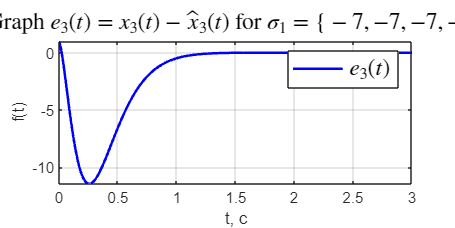


plot(out.e.Time,out.e.Data(:,3),'b', 'LineWidth', 1.5)
%hold on
%plot(t, y,'b--', 'LineWidth', 1.5)

grid("on")
title('Graph $e_3(t)=x_3(t) - \hat{x}_3 (t)$ for $\sigma_1= \{ -7, -7, -7, -7 \}$', 'Interpreter','latex',  'FontSize', 14)
legend('$e_3(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')

%ylim([-7 1])
%hold off


